# Introducao

clear all;       %limpa variaveis
close all;       %limpa os graficos/figuras
clc;            %limpa a tela

## Definindo variaveis

A = 1             %variavel real

A = 1

B = 1+j           %variavel complexa

B = 1.0000 + 1.0000i

C = magic(3)      %matriz

C =      8     1     6
     3     5     7
     4     9     2


D = rand(7)       %aleatoria

D =     0.8178    0.1788    0.6385    0.8200    0.7788    0.5271    0.2407
    0.2607    0.4229    0.0336    0.7184    0.4235    0.4574    0.6761
    0.5944    0.0942    0.0688    0.9686    0.0908    0.8754    0.2891
    0.0225    0.5985    0.3196    0.5313    0.2665    0.5181    0.6718
    0.4253    0.4709    0.5309    0.3251    0.1537    0.9436    0.6951
    0.3127    0.6959    0.6544    0.1056    0.2810    0.6377    0.0680
    0.1615    0.6999    0.4076    0.6110    0.4401    0.9577    0.2548


## Operacoes logicas

[I,J,V] = find(C==5)

I = 2

J = 2

V = logical
   1


E = [1 2 3 4 5 6 7 8 9 10]

E =      1     2     3     4     5     6     7     8     9    10


E>5

ans = 1×10 logical array
   0   0   0   0   0   1   1   1   1   1


## Operacoes simbolicas

syms t a                      %variaveis simbolicas
I = int(exp(-a*t),t,0,1)      %integral

$$I = -\frac{{\mathrm{e}}^{-a}-1}{a}$$

a = 1

a = 1

eval(I)                       % calcula numericamente

ans = 0.6321

## Funcao handle

g = @(a,t)  exp(-a*t)      %define funcao

g = function_handle with value:
    @(a,t)exp(-a*t)


g(1,1)

ans = 0.3679

## Documentacao e visualizacao

tempo = [0:0.1:2*pi]

tempo =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


y = sin(tempo)

y =          0    0.0998    0.1987    0.2955    0.3894    0.4794    0.5646    0.6442    0.7174    0.7833    0.8415    0.8912    0.9320    0.9636    0.9854    0.9975    0.9996    0.9917    0.9738    0.9463    0.9093    0.8632    0.8085    0.7457    0.6755    0.5985    0.5155    0.4274    0.3350    0.2392    0.1411    0.0416   -0.0584   -0.1577   -0.2555   -0.3508   -0.4425   -0.5298   -0.6119   -0.6878   -0.7568   -0.8183   -0.8716   -0.9162   -0.9516   -0.9775   -0.9937   -0.9999   -0.9962   -0.9825


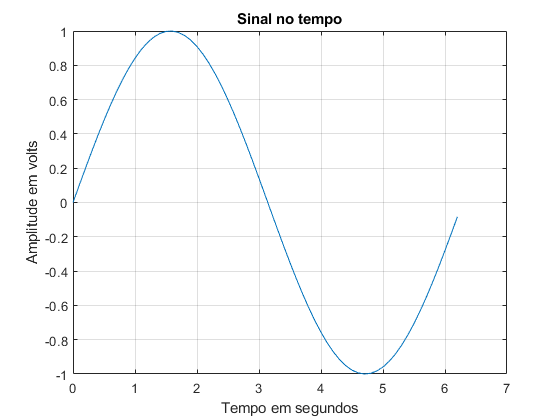

figure(1)
plot(tempo,y);
title("Sinal no tempo");
xlabel("Tempo em segundos");
ylabel("Amplitude em volts");
grid;


y1 = sin(2*tempo)

y1 =          0    0.1987    0.3894    0.5646    0.7174    0.8415    0.9320    0.9854    0.9996    0.9738    0.9093    0.8085    0.6755    0.5155    0.3350    0.1411   -0.0584   -0.2555   -0.4425   -0.6119   -0.7568   -0.8716   -0.9516   -0.9937   -0.9962   -0.9589   -0.8835   -0.7728   -0.6313   -0.4646   -0.2794   -0.0831    0.1165    0.3115    0.4941    0.6570    0.7937    0.8987    0.9679    0.9985    0.9894    0.9407    0.8546    0.7344    0.5849    0.4121    0.2229    0.0248   -0.1743   -0.3665



figure(2)
plot(tempo,y);hold;plot(tempo,y1);

Current plot held


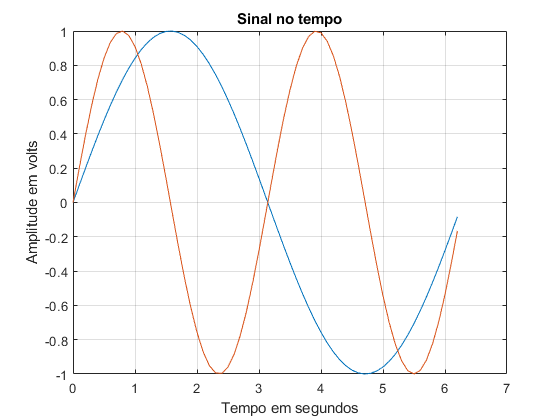

title("Sinal no tempo");
xlabel("Tempo em segundos");
ylabel("Amplitude em volts");
grid;

## Arquivos externos

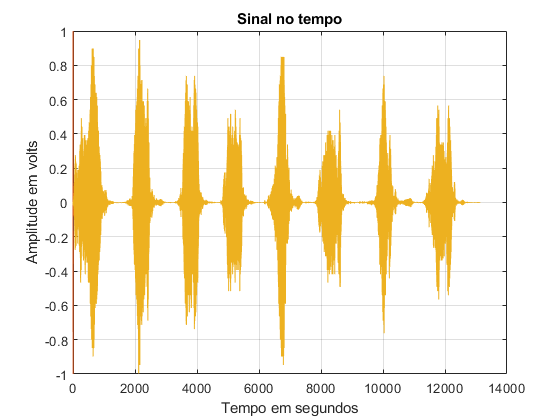

load chirp
plot(y)

sound(y);        %som

Xp=mean(y)       %media

Xp = 2.3052e-04


Vp = var(y)      %variancia

Vp = 0.0373


Yc=[y;y]        %concatena

Yc =    -0.0015
         0
   -0.0008
   -0.0127
    0.0038
   -0.0077
   -0.0115
    0.0046
   -0.0173
    0.0046



Yl = [y' y']     %concatena

Yl =    -0.0015         0   -0.0008   -0.0127    0.0038   -0.0077   -0.0115    0.0046   -0.0173    0.0046   -0.0008   -0.0092    0.0115   -0.0092    0.0008    0.0085   -0.0046    0.0038    0.0188   -0.0100    0.0235    0.0015   -0.0038    0.0342   -0.0250    0.0250   -0.0085   -0.0108    0.0381   -0.0265    0.0235    0.0062   -0.0381    0.0565   -0.0381    0.0127    0.0281   -0.0688    0.0950   -0.0781    0.0358    0.0265   -0.0888    0.1135   -0.0842    0.0235    0.0381   -0.1012    0.1196   -0.0812



Ep = y.^2      %conta com os numeros na matriz

Ep =     0.0024
         0
    0.0006
    0.1611
    0.0148
    0.0592
    0.1331
    0.0213
    0.2996
    0.0213


## Estrutura de dados

D = {}


D =

  0×0 empty cell array



D.data = Yc

D = struct with fields:
    data: [26258×1 double]


D.tempo = Yl

D = struct with fields:
     data: [26258×1 double]
    tempo: [1×26258 double]
